# Enhanced Uplink Performance via RIS-Assisted LLR and Channel Estimation

## **Experimental code - A Probability Approach and the outcomes in ** BER and Sum-Rate.

**Author:** Roberto Câmara (camara2k@gmail.com/ camara@ime.eb.br)

**Prototype Start Date:** Set/2024

### Introduction to the Code: 

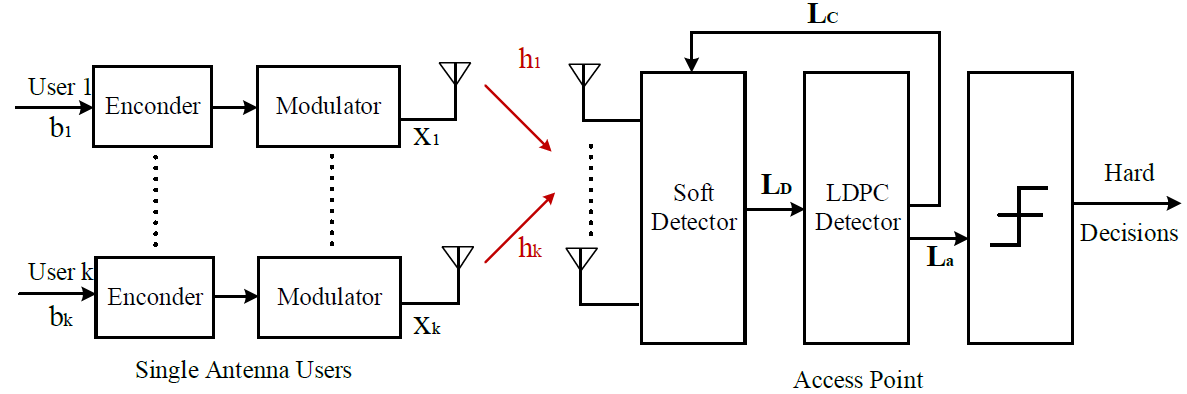

### Numerical Results of the Code: 

The code generates estimates of the BER and Sum-Rate for a system under three scenarios: perfect CSI, estimated CSI, and estimated CSI with LLR refinement. The objective is to explore potential performance improvements in both BER and Sum-Rate when leveraging the outcomes of the LLRs and the symbols to enhance channel estimation.

### Basic Variables:

- **Number of Tx:** 4.

- **Number of Rx:** 8.

- **IDD iterations:** 3.

- **Refinement iterations:** 2.

- **Power per user:** 8:20 dBm.

- **Number of packages:** 2500.

- **Noise power:** -100 dBm.

- **Distance:** 400m, assuming a 3GPP standard weak signal between the users and the Access Point (AP).

### Define if the process will involve parallel looping or not.

clear; close all; clc
% Define if the simulation will be run in parallel-------------------------------
% It is also needed to manually change the inner loop 'for' to 'parfor'!
useParallel = true;
% Progress bar ------------------------------------------------------------------
if ~useParallel
    f = waitbar(0, 'Starting');
end

### Setup variables

format long
% addpath('ldpc','functions','results','data','experimental','optimization','functionsEstimated')
warning('off')

% Simulation (defined by the user) --------------------------------------------------------------
Packets = [25 25 50 50 100 100 150];   % Number of Packets to Send
Pw_user_dBm = 8:14;                         % Power per user in dBm
sigma_n2_dbm = -100;                        % Noise in dBm

if length(Packets) ~= length(Pw_user_dBm)
   error('Error Packets and Pw_user_dBm vectors must have the same size')
end

% System Initialization
[sys,enviroment,estimation,idd1,idd3] = initializeSystem_1(Pw_user_dBm,sigma_n2_dbm);

% Methods Evaluated in Simulation ---------------------------------------------------------------
methods = [
"IDD MMSE W/O-RIS \tau = 3 perfect CSI"
"IDD MMSE W/O-RIS \tau = 3 estimated CSI"
"IDD MMSE W/O-RIS \tau = 3 estimated CSI"
];

% Auxiliar variables ---------------------------------------------------------------------------
PacketBitLength = sys.PacketDataLength*sys.n_tx;
numberofmethods = length(methods);
numPWR = length(Pw_user_dBm);        
DateI = datetime('now');

% Variables Initialization----------------------------------------------------------------------
RsumVec = zeros(numberofmethods,numPWR);
BerVec  = zeros(numberofmethods,numPWR);
NMSE_1 = zeros(sys.n_tx,numPWR);
NMSE_2 = zeros(sys.n_tx,numPWR); 

### **Main Function **

for pwr = 1:numPWR
    printStatus(pwr,Pw_user_dBm)
    % Auxiliar variables in the loop ------------------------------
    RsumVec_aux = zeros(numberofmethods,length(Packets));
    BerVec_aux = zeros(numberofmethods, length(Packets));
    NMSE_num_aux = zeros(sys.n_tx,length(Packets));
    NMSE_den_aux = zeros(sys.n_tx,length(Packets));
    NMSE_num2_aux = zeros(sys.n_tx,length(Packets));
    NMSE_den2_aux = zeros(sys.n_tx,length(Packets)); 

    parfor NumPackets = 1:Packets(pwr)
        % init variables ------------------------------------------
        Ber = zeros(length(methods),1);
        Rsum = zeros(length(methods),1);

        % Channel coefficients generation ----------------------------------------------------------------------------
        channel = generateRayleight(sys,enviroment,'weak');
        [channel,a1] = channelDirectEstimation(sys,channel, estimation, true, pwr);
        [channel,b]= channelPrisEstimation(sys, channel, estimation, false, pwr);

        % Perfect CSI ------------------------------------------------------------------------------------------------
        [bErrors, Rsum_aux] = IDD_MMSE_WithoutRIS(sys,channel,idd3,pwr,true,0,0);
        Ber(1) = bErrors/(PacketBitLength);
        Rsum(1) = Rsum_aux;
        % Estimated CSI --------------------------------------
        [bErrors, Rsum_aux, P_extra, Y_extra] = IDD_MMSE_WithoutRIS(sys,channel,idd3,pwr,false,'probabilistic',0.85);
        Ber(2) = bErrors/(PacketBitLength);
        Rsum(2) = Rsum_aux;
        % Estimated and Refined CSI --------------------------
        [channel2,a2] = channelDirectEstimation2(sys, channel, estimation, true, pwr, P_extra, Y_extra);
        [bErrors,Rsum_aux,~,~] = IDD_MMSE_WithoutRIS(sys,channel2,idd3,pwr,false,'probabilistic',0.85);
        Ber(3) = bErrors/(PacketBitLength);
        Rsum(3) = Rsum_aux;

        %Ber and Sum-rate Matrix generation
        BerVec_aux(:,NumPackets)    = Ber;
        RsumVec_aux(:,NumPackets)   = Rsum;
        NMSE_num_aux(:,NumPackets)  = sum(abs(channel.H-channel.H_est).^2);
        NMSE_den_aux(:,NumPackets)  = sum(abs(channel.H).^2);
        NMSE_num2_aux(:,NumPackets) = sum(abs(channel2.H-channel2.H_est).^2);
        NMSE_den2_aux(:,NumPackets) = sum(abs(channel2.H).^2); 

        % Wait bar -----------------------------------------------------------------
        if ~useParallel
            aux = ((pwr-1)*Packets)+NumPackets;
            waitbar(aux/(numPWR*Packets), f, sprintf('Progress: %d %%', floor(aux*100/(numPWR*Packets))   ));
        end
    end    
    % update ber and Rsum vector ----------------------------------------------------
    BerVec(:,pwr) = mean(BerVec_aux,2);
    RsumVec(:,pwr) = mean(RsumVec_aux,2);
    NMSE_1(:,pwr) = sum(mean(NMSE_num_aux,3),2)./sum(mean(NMSE_den_aux,3),2);
    NMSE_2(:,pwr) = sum(mean(NMSE_num2_aux,3),2)./sum(mean(NMSE_den2_aux,3),2);

    % time tracking -----------------------------------------------------------------
    Date = datetime('now');
    Dur = Date-DateI;

    % automatic saving per iteration ------------------------------------------------
    save('data/main.mat');
end

SNR:    14

### **Plots**

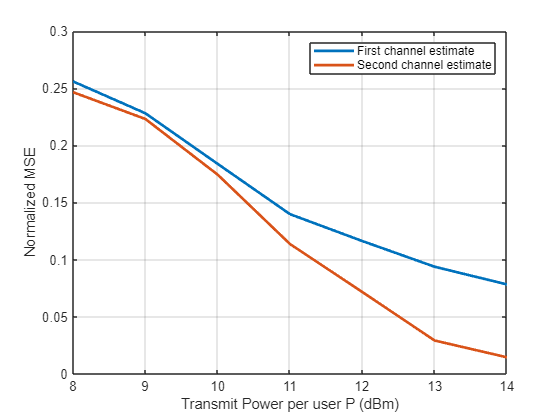

generatePlot_NMSE(NMSE_1,NMSE_2,Pw_user_dBm)

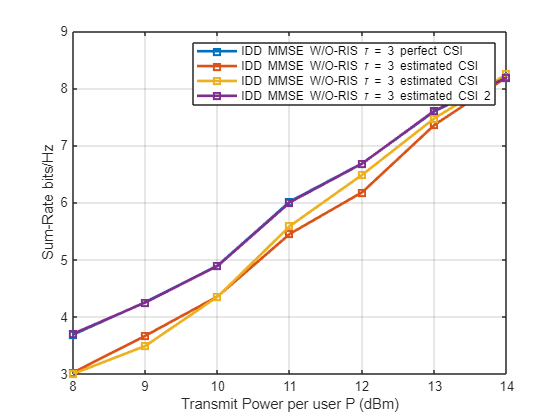

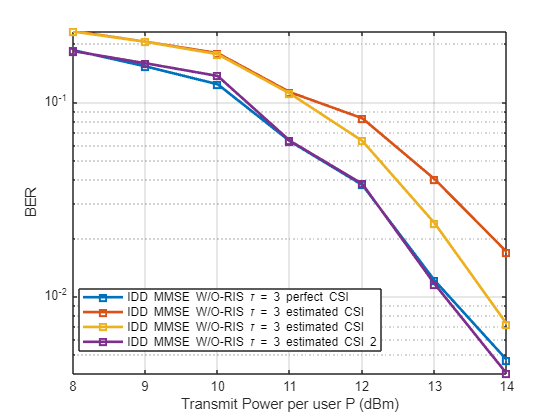

generatePlots4(methods, Pw_user_dBm,BerVec,RsumVec,0)

if ~useParallel
    close(f);
end
